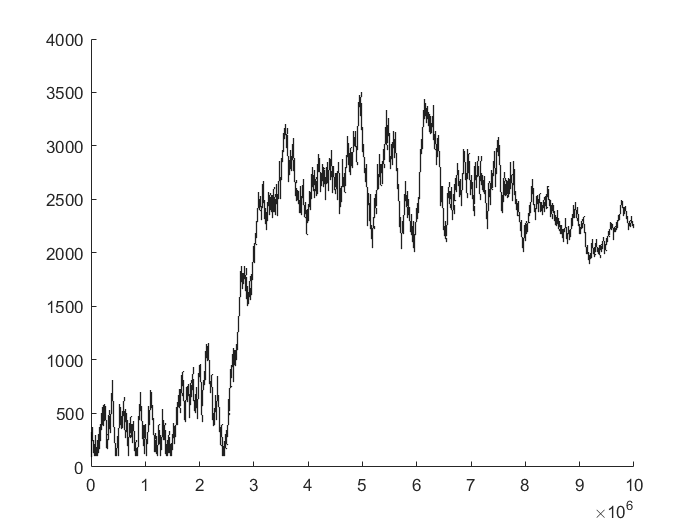

above=1;
below=1;
difference=[];
itterations=10000;
outputs=[];
rows=1000;
for r=1:rows
    for i=1:itterations
        outputs(r,i)=sin(f(i,r));
        if(sin(f(i,r))>0)
            above=above+1;
        elseif(sin(f(i,r))<0)
            below=below+1;
        end
        difference(i+(r-1)*itterations)=abs(above-below)+100;
    end
end
%{
hold on
figure;
scatter(1:itterations,difference,1,'black','filled');
xlim([0 itterations])
hold off
%}
scatter(1:(itterations*rows),difference,1,'black','filled');

function y = f(x,a)
    y=sin(x^((a+10)/10))*(x);
end